%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Davide Cunial 20 Ottobre 2016
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Extraction

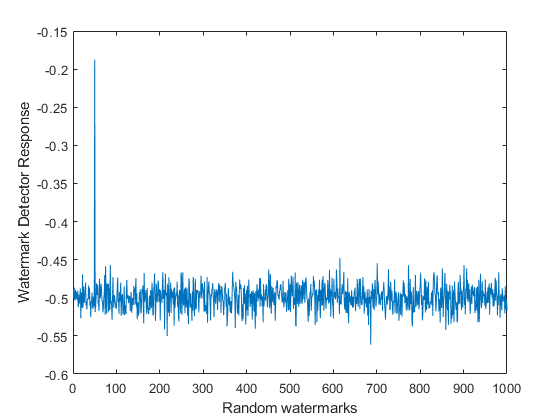

extracted_w = zeros(1,1024);
original_w=zeros(1,1024);
Iatt=I_inv;
%Iatt = imsharpen(Iatt, 'Radius', 100, 'Amount', 100);
%Iatt=test_resize(Iatt, 0.23);
%rng(7); % Seed random generator
%Iatt = imnoise(uint8(Iatt),'gaussian',0, 0.04);
%Iatt = imgaussfilt(Iatt,2.2);
%imwrite(uint8(Iatt), 'SSatt.jpg', 'Quality', 8);
%Iatt = imread('SSatt.jpg');
%delete('SSatt.jpg');
%Iatt=test_blur(Iatt,8);
%Iatt=test_median(Iatt,6,6);
%Iatt=test_equalization(uint8(Iatt),2);


Iatt_re = dct2(Iatt);
Iatt_re = abs(reshape(Iatt_re,1,dimx*dimy));
k = 49380;
for j = 1:1024
    m = Ix(k);
    extracted_w(j) = (Iatt_re(m)/It_mod(m) - 1)/alpha;
    original_w(j) = (Itw_mod(m)/It_mod(m) - 1)/alpha;
%    Itw_mod(m) = It_mod(m)*(1+alpha*w(j));
   % k =round(k+(div/k));
   k=k+1;
   if(j==1)
        k=50000;
    end
end

rng(7);
w_new=zeros(1000,1024);
for n = 1:49
    w_new(n,:) = round(rand(1,1024));
end
w_new(50,:) = original_w;
for n =51:1000
    w_new(n,:) = round(rand(1,1024));
end

sim=zeros(1,1000);
for n = 1:1000
    sim(n) = extracted_w.*w_new(n,:)/sqrt(extracted_w.*extracted_w);
end

x = 1:1000;
plot(x,sim); xlabel('Random watermarks'); ylabel('Watermark Detector Response');

wpsnr=WPSNR(uint8(I_inv),uint8(Iatt))

wpsnr = 28.6965

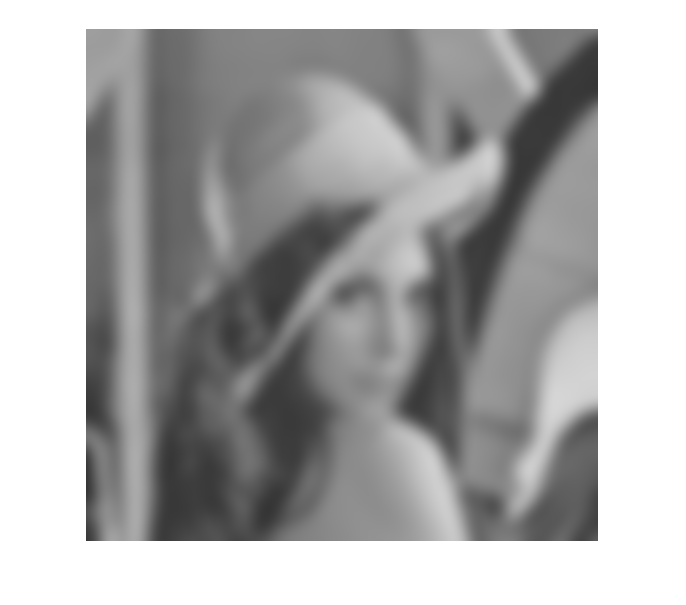


sorted=sort(sim,'descend');
figure(); imshow(uint8(Iatt));

ss=sorted(2)*(1.1);
if(sorted(2)<0)
     ss=sorted(2)*(0.9);
end
if(sim(50)>ss)
    	fprintf('true\n');
else
    fprintf('false\n');
end

true
